# **Eksamen M4STI1 2020F**

### Løsningsforslag af Allan Leck Jensen

## Opgave 1 - Den tidlige udvikling af coronavirus i Italien

**Oplysninger i opgaven:**

clear; close all; clc; format compact;

n = 3300                    % Antal indbyggere i Vo'

n = 3300

n_C1 = 89                   % Antal positive Covid-19 tests d. 6. marts

n_C1 = 89

n_C2 = 6                    % Antal positive Covid-19 tests d. 20. marts

n_C2 = 6

n_C3 = 0                    % Antal positive Covid-19 tests d. 3. april

n_C3 = 0

**a.  Sandsynligheden for at være testet positiv på datoerne 6. marts, 20. marts og 3. april**

Sandsynlighederne beregnes som antal personer, der er testet positive på datoen, delt med antal testede (dvs. antal indbyggere)

P_C1 = n_C1 / n             % P(C1)

P_C1 = 0.0270

P_C2 = n_C2 / n             % P(C2)

P_C2 = 0.0018

P_C3 = n_C3 / n             % P(C3) 

P_C3 = 0

**b.  Positive både 6. marts og 20. marts**

Alle 6, der blev testet positiv den 20/3 var også positive den 6/3, så der er 6 personer i fælleshændelsen mellem C2 og C1. For at få sandsynligheden for fælleshændelsen deler vi med antal testede, n. For at få sandsynligheden for den betingede sandsynlighed af C2 givet C1 deler vi med antal i C1, n_C1:

n_C2_faelles_C1 = 6

n_C2_faelles_C1 = 6

P_C2_faelles_C1 = n_C2_faelles_C1 / n               % P(C2 n C1) 

P_C2_faelles_C1 = 0.0018

P_C2_givet_C1   = n_C2_faelles_C1 / n_C1            % P(C2|C1) 

P_C2_givet_C1 = 0.0674

**c.  Betingede sandsynligheder for at udvise symptomer**

Nye oplysninger i teksten:

n_pos_uden_symp = 63            % Der er 63 testet positiv, men uden symptomer

n_pos_uden_symp = 63

n_neg_med_symp = 125            % Der er 125 testet negativ, men med symptomer

n_neg_med_symp = 125

Vi skal finde antal personer med symptomer blandt dem, der blev testet positiv d. 6. marts. Ud af 89 positive havde 69 ingen symptomer. De resterende 89-63 = 26 havde, så n_pos_med_symp = 26:

n_pos_med_symp = n_C1 - n_pos_uden_symp         % Antal positive med symptomer

n_pos_med_symp = 26

P_S1_givet_C1 = n_pos_med_symp / n_C1                   % P(S1 | C1) 

P_S1_givet_C1 = 0.2921

P_S1c_givet_C1 = 1 - P_S1_givet_C1                      % P(S1c | C1)

P_S1c_givet_C1 = 0.7079

P_S1_givet_C1c = n_neg_med_symp / (n - n_C1)            % P(S1 | C1c)

P_S1_givet_C1c = 0.0389

**d.  Den totale sandsynlighed for at udvise symptomer**

Dem med symptomer er dels dem der tester positiv og har symptomer og dels dem, der tester negativ, men alligevel har symptomer. Jeg bruger 'loven om den totale sandsynlighed':

P(S1) = P(S1|C1) * P(C1) + P(S1|C1c) * P(C1c)

P_S1 = P_S1_givet_C1 * P_C1 + P_S1_givet_C1c * (1 - P_C1)           % P(S1)

P_S1 = 0.0458

**e.  Sandsynligheden for at blive testet positiv blandt personer med symptomer**

Vi skal bruge Bayes' formel:

P(C1|S1) = P(S1|C1)*P(C1)/P(S1)

P_C1_givet_S1 = P_S1_givet_C1 * P_C1 / P_S1                     % P(C1 | S1)

P_C1_givet_S1 = 0.1722

------------------------------------------------------------------------------------------------------------------------------------------

## Opgave 2 - Undersøgelse af inkubationstiden for Covid-19

Jeg starter med at rydde op:

clc; clear; close all; format compact; 

**Oplysninger i opgaven:**

Den naturlige logaritme til inkubationstiden er normalfordelt med disse parametre:

mu = 1.6196                         % Middelværdi 

mu = 1.6196

sigma = 0.4187                      % Standardafvigelse

sigma = 0.4187

**a.  Hvor stor en andel har inkubationstid på over 14 døgn?**

inku_14 = 14

inku_14 = 14

Jeg tager den naturlige logaritme til inkubationstiden, for så følger den normalfordelingen: 

log_inku_14 = log(inku_14)

log_inku_14 = 2.6391

andel_inku_under_14 = normcdf(log_inku_14, mu, sigma)

andel_inku_under_14 = 0.9926

andel_inku_over_14 = 1 - andel_inku_under_14

andel_inku_over_14 = 0.0074

Vi finder altså, at 0.7% har inkubationstid over 14 døgn.

**b.  Median for inkubationstiden**

Først finder vi medianen på den normalfordelte skala, hvor vi har taget logaritmen til inkubationstiden. Medianen er den værdi, der deler arealet under kurven i to halvdele (for symmetriske fordelinger som normalfordelingen er medianen lig med middelværdien):

log_medi = norminv(0.5, mu, sigma)

log_medi = 1.6196

Dernæst transformerer vi om til inkubationstid ved at tage exp()

medi = exp(log_medi)

medi = 5.0511

Medianen er 5.0511 døgn, hvilket kan rundes op til 5.1 døgn.

**c.  Hvornår har 95% af smittede udvist symptomer?**

Vi finder først den værdi på den normalfordelte, logaritmiske skala, der har et areal under kurven nedadtil på 0.95:

log_inku_95 = norminv(0.95, mu, sigma)

log_inku_95 = 2.3083

Dernæst omregnes den til inkubationstid ved at tage exp():

inku_95 = exp(log_inku_95)

inku_95 = 10.0573

Efter 10.0573 døgn har 95 pct af smittede udvist symptomer.

**d.  Empirisk interval**

På den normalfordelte skala er det empiriske interval:

logEI_lav  = mu - 3*sigma

logEI_lav = 0.3635

logEI_hoej = mu + 3*sigma

logEI_hoej = 2.8757

Nu konverterer jeg grænserne for det empiriske interval til inkubationstider ved at tage exp(): 

EI_lav  = exp(logEI_lav)

EI_lav = 1.4384

EI_hoej = exp(logEI_hoej)

EI_hoej = 17.7378

Næsten alle patienter vil altså vise symptomer indenfor en periode af 1.4 til 17.7 døgn.

------------------------------------------------------------------------------------------------------------------------------------------

## Opgave 3 - Udviklingen af dødstal i Danmark og Sverige

Jeg starter med at rydde op og indlæse data fra regnearket:

clc; clear; close all; format compact; 
D = xlsread('Data_M4STI1_2020F', 'A:D');
dagnr = D(:,1);
dk_total = D(:,2);  
se_total = D(:,3);
% Regnearkets fjerde kolonne med dato skal vi ikke bruge, da vi har dagnummer

**a.  Samlet graf over udviklingen af døde i Danmark og Sverige**

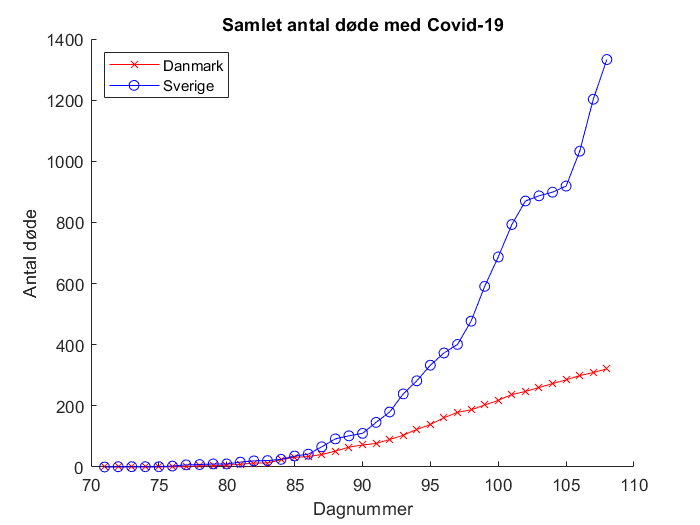

figure(1)
hold on;
plot(dagnr, dk_total, 'rx-')
plot(dagnr, se_total, 'bo-')
hold off;
title('Samlet antal døde med Covid-19')
xlabel('Dagnummer')
ylabel('Antal døde')
legend('Danmark', 'Sverige', 'Location', 'northwest')

**b.  Justering af data og graf med de justerede data**

Data beregnes i forhold til landenes indbyggertal, og data for de første 10 dage fjernes. 

pop_dk = 5.8                        % Antal millioner indbyggere i Danmark

pop_dk = 5.8000

pop_se = 10.3                       % Antal millioner indbyggere i Sverige

pop_se = 10.3000

dk_mio = D(:,2)./pop_dk;            % Antal døde med Covid-19 pr million i DK
se_mio = D(:,3)./pop_se;            % Antal døde med Covid-19 pr million i SE

startdag = 11                       % Smid data for de første 10 dage væk

startdag = 11

slutdag = size(dagnr,1)

slutdag = 38

dk_mio2 = dk_mio(startdag:slutdag);
se_mio2 = se_mio(startdag:slutdag);
dagnr2  = dagnr(startdag:slutdag);

Der laves en ny figur med de modificerede data:

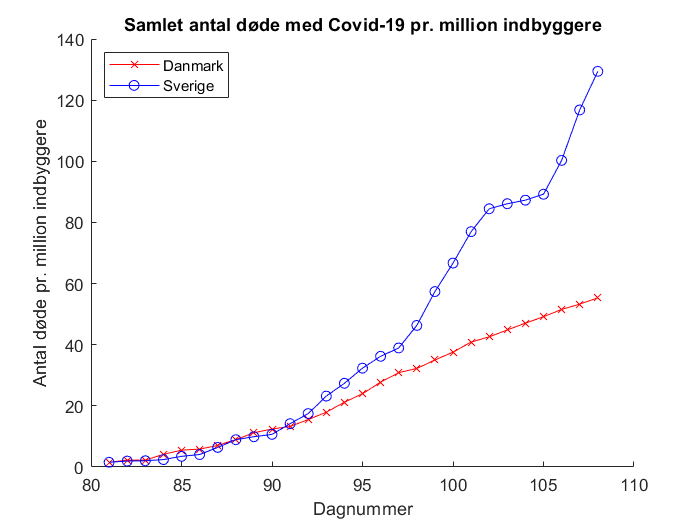

figure(2)
hold on;
plot(dagnr2, dk_mio2, 'rx-')
plot(dagnr2, se_mio2, 'bo-')
hold off;
title('Samlet antal døde med Covid-19 pr. million indbyggere')
xlabel('Dagnummer')
ylabel('Antal døde pr. million indbyggere')
legend('Danmark', 'Sverige', 'Location', 'northwest')

**c.  Lineære modeller for DK og SE**

Der laves lineære modeller med funktionen fitlm:

mdl_lin_dk = fitlm(dagnr2, dk_mio2)

mdl_lin_dk = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________
    (Intercept)    -180.35       5.4683    -32.981     9.582e-23
    x1              2.1735     0.057656     37.698    3.1772e-24

Number of observations: 28, Error degrees of freedom: 26
Root Mean Squared Error: 2.46
R-squared: 0.982,  Adjusted R-Squared: 0.981
F-statistic vs. constant model: 1.42e+03, p-value = 3.18e-24

mdl_lin_se = fitlm(dagnr2, se_mio2)

mdl_lin_se = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________
    (Intercept)    -394.07      26.057    -15.123    2.1275e-14
    x1              4.6168     0.27473     16.805    1.7548e-15

Number of observations: 28, Error degrees of freedom: 26
Root Mean Squared Error: 11.7
R-squared: 0.916,  Adjusted R-Squared: 0.912
F-statistic vs. constant model: 282, p-value = 1.75e-15

Modelligningerne opskrives:

C_lin_dk = -180.35 + 2.1735*t

C_lin_se = -394.07 + 4.6168*t

**d.  Er det gode modeller?**

Begge lineære modeller er gode, ifølge statistikkerne for den lineære regression. Koefficienterne i begge modeller er signifikant forskellige fra nul med meget lave p-værdier (største p-værdi er 2.1e-14, altså meget tæt på 0). Den danske model beskriver variationen i data bedre end den svenske, da R-squared er 0.982, mod 0.916 i den svenske. Adjusted R-squared er tæt på R-squared for begge modeller med hhv. 0.981 og 0.912, så modellerne overfitter ikke.  Grafen fra delspørgsmål b. viser dog, at begge kurver ikke forløber lineært. Især viser kurven for Sverige et stigende forløb, så måske er en polynomiel eller en eksponentiel model bedre.

**e.  Hvornår nås 1000 døde?**

For en lineær funktion y = b0 + b1*x kan vi isolere x:

     x = (y - b0)/b1

Derfor gælder for den danske model:

     t_lin_dk = (1000 + 180.35)/2.1735

t_lin_dk = (1000 + 180.35)/2.1735

t_lin_dk = 543.0642

... og for den svenske:

     t_lin_se = (1000 + 394.07)/4.6168

t_lin_se = (1000 + 394.07)/4.6168

t_lin_se = 301.9559

Danmark forventes at runde 1000 døde pr. million på dag nummer 543 (inden dag nummer 544), mens Sverige gør det allerede på dag nummer 301 (lige inden starten af dag 302).

**f.  Unormale punkter**

Studentiserede residualer og hatdiagonal for den danske model:

rst_lin_dk = mdl_lin_dk.Residuals.Studentized;
lev_lin_dk = mdl_lin_dk.Diagnostics.Leverage;

Studentiserede residualer og hatdiagonal for den svenske model:

rst_lin_se = mdl_lin_se.Residuals.Studentized;
lev_lin_se = mdl_lin_se.Diagnostics.Leverage;

Grænseværdi for løftestangspunkt beregnes:

k = 1                           % Antal regressorvariable i hver model

k = 1

n = size(dagnr2,1)               % Antal observationer bag hver model

n = 28

lev_limit = 2*(k+1)/n           % Grænseværdi lev_limit = 0.1429

lev_limit = 0.1429

Test for om der er **outliers** i den **danske** **model**. 

Hvis den absolutte værdi af det studentiserede residual er over 3, så er det en outlier. Jeg bruger denne kode i stedet for at gå tallene igennem manuelt:

if any(abs(rst_lin_dk) > 3)
    disp('Der er mindst en outlier i den danske model')
else
    disp('Der er ingen outliers i den danske model')
end

Der er ingen outliers i den danske model


Test for om der er **outliers** i den **svenske** **model**.

if any(abs(rst_lin_se) > 3)
    disp('Der er mindst en outlier i den svenske model')
else
    disp('Der er ingen outliers i den svenske model')
end

Der er ingen outliers i den svenske model


Test for om der er **løftestangspunkter** i den **danske model**. 

Hvis et punkts hatdiagonal er over grænseværdien lev_limit, er det et løftestangspunkt.

if any(lev_lin_dk > lev_limit)
    disp('Der er mindst et løftestangspunkt i den danske model')
else
    disp('Der er ingen løftestangspunkter i den danske model')
end

Der er ingen løftestangspunkter i den danske model


Test for om der er **løftestangspunkter** i den **svenske model**. 

if any(lev_lin_se > lev_limit)
    disp('Der er mindst et løftestangspunkt i den svenske model')
else
    disp('Der er ingen løftestangspunkter i den svenske model')
end

Der er ingen løftestangspunkter i den svenske model


Der er ingen unormale punkter, hverken outliers eller løftestangspunkter, og derfor heller ingen inflydelsespunkter. Det gælder for begge modeller. 

**g.  Eksponentiel model for Danmark og Sverige**

Hvis modellen er eksponentiel, bliver den lineær ved at tage logaritmen på begge sider af lighedstegnet:

     C = B*exp(A*t) => log(C) = log(B) + A*t

En lineær regression vil altså give koefficienterne log(B) og A, hvor log(B) er skæring med andenaksen og A er hældningkoefficienten.

log_dk = log(dk_mio2);
log_se = log(se_mio2);

mdl_exp_dk = fitlm(dagnr2, log_dk)

mdl_exp_dk = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________
    (Intercept)    -8.9644       0.67867    -13.209    4.8533e-13
    x1             0.12465     0.0071556     17.421    7.4086e-16

Number of observations: 28, Error degrees of freedom: 26
Root Mean Squared Error: 0.306
R-squared: 0.921,  Adjusted R-Squared: 0.918
F-statistic vs. constant model: 303, p-value = 7.41e-16

mdl_exp_se = fitlm(dagnr2, log_se)

mdl_exp_se = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________
    (Intercept)    -12.904       0.63134    -20.439    1.5291e-17
    x1             0.16878     0.0066566     25.355    7.3044e-20

Number of observations: 28, Error degrees of freedom: 26
Root Mean Squared Error: 0.285
R-squared: 0.961,  Adjusted R-Squared: 0.96
F-statistic vs. constant model: 643, p-value = 7.3e-20

Dansk eksponentiel model:

     log(C_exp_dk) = -8.9644 + 0.12465*t

     C_exp_dk = exp(-8.9644 + 0.12465*t)

     C_exp_dk = exp(-8.9644)*exp(0.12465*t) = (1.2788e-04)*exp(0.12465*t)

Svensk eksponentiel model:

     C_exp_se = exp(-12.904)*exp(0.16878*t) = (2.4881e-06)*exp(0.16878*t)

**Ekstra - ikke en del af opgaven.**

Jeg vil gerne plotte den lineære og den eksponentielle model mod data for de to lande:

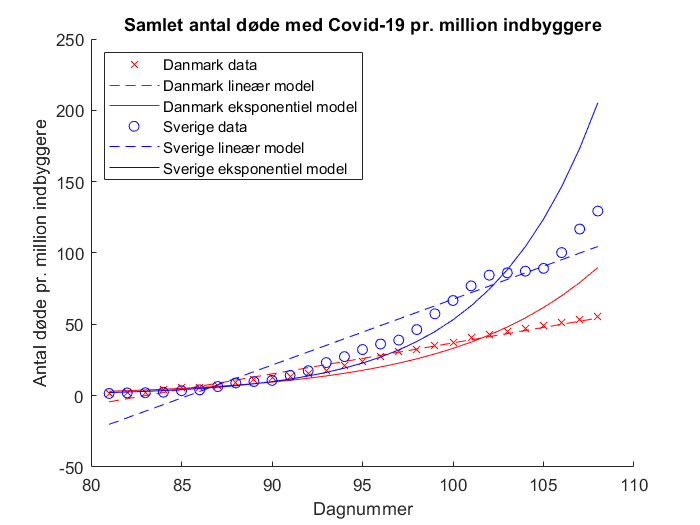

C_lin_dk = -180.35 + 2.1735*dagnr2;
C_lin_se = -394.07 + 4.6168*dagnr2;
C_exp_dk = 1.2788e-04*exp(0.12465*dagnr2);
C_exp_se = (2.4881e-06)*exp(0.16878*dagnr2);

figure(3)
hold on;
plot(dagnr2, dk_mio2, 'rx')
plot(dagnr2, C_lin_dk, 'r--')
plot(dagnr2, C_exp_dk, 'r-')
plot(dagnr2, se_mio2, 'bo')
plot(dagnr2, C_lin_se, 'b--')
plot(dagnr2, C_exp_se, 'b-')
hold off;
title('Samlet antal døde med Covid-19 pr. million indbyggere')
xlabel('Dagnummer')
ylabel('Antal døde pr. million indbyggere')
legend('Danmark data', 'Danmark lineær model', 'Danmark eksponentiel model', ...
    'Sverige data', 'Sverige lineær model', 'Sverige eksponentiel model', ...
    'Location', 'northwest')

**h.  Hvilken model er bedst for de to lande? **

Ifølge statistikkerne for linær regression er både den lineære og den eksponentielle model gode til at beskrive udviklingen af antal døde pr. million indbyggere for både Danmark og Sverige. I alle fire modeller er R-squared over 0.90, så en stor del af variationen i data beskrives af modellerne. Adjusted R-squared er i alle tilfælde en anelse mindre end R-squared, og alle koefficienter er signifikante med meget små p-værdier. Så alle fire modeller er gode.

Dog er det tydeligt fra figuren fra delspørgsmål b., at udviklingen ser mest lineær ud i Danmark og mest eksponentiel ud i Sverige.

Vi kan også se af R-squared, at det forholder sig sådan. For Danmark er R-squared = 0.98 for den lineære model mod 0.92 for den eksponentielle. For Sverige er det den eksponentielle model, der beskriver variationen i data lidt bedre end den lineære, da R-squared er 0.96 for den eksponentielle og 0.92 for den lineære.

Derfor vil jeg vælge den lineære model for Danmark og den eksponentielle model for Sverige. Det kunne være en teori, at forskellene i udvikling skyldes forskellene i bekæmpelsesstrategi, hvor den danske regering har indført mere restriktive tiltag for at reducere en for voldsom smittespredning.